close("all"); clear; clc;

A = [
    0,1;
    0,0
    ];

B = [
    0;
    1
    ];

C = eye(2);

D = 0;

sys = ss(A,B,C,D);
ts = 0.02;
sysd = c2d(sys,ts);

pmax = 1;
pmin = -1;
vmax = 1;
vmin = -1;

x0 = [
    pmin,vmin;
    pmin,vmax;
    pmax,vmax;
    pmax,vmin
    ].';

X = zonotope2d(x0);

umax = 0.1;
umin = -0.1;
U = zonotope2d([B*umin,B*umax]);

R = {X};
V = U;
S = zonotope2d(zeros(2,1));

for k = 1:100
    X = sysd.A*X;
    S = S + V;
    V = sysd.A*V;
    R{k} = X + S;
end
R = [R{:}];

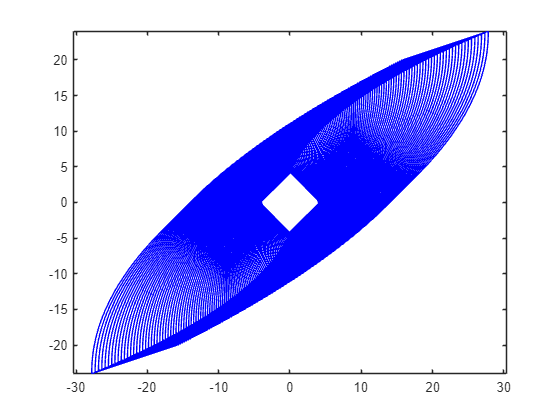

fig = figure();
axe = axes(fig);
arrayfun(@plot,R);
axis(axe,"equal");
box(axe,"on");